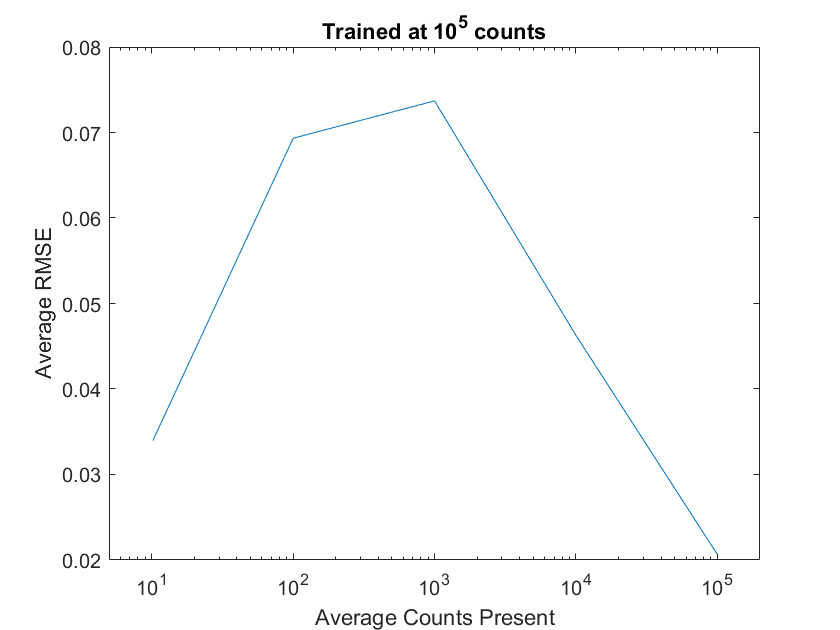

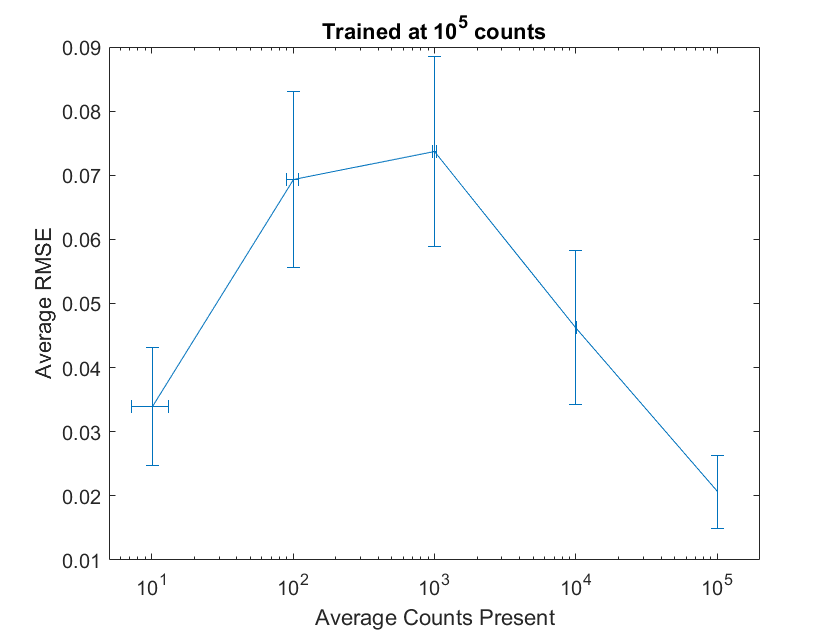

x = 1

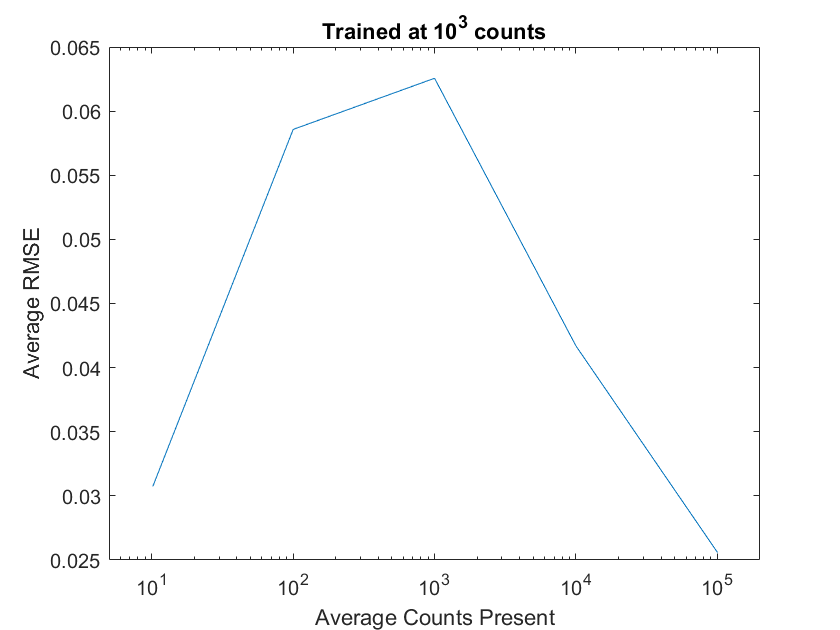

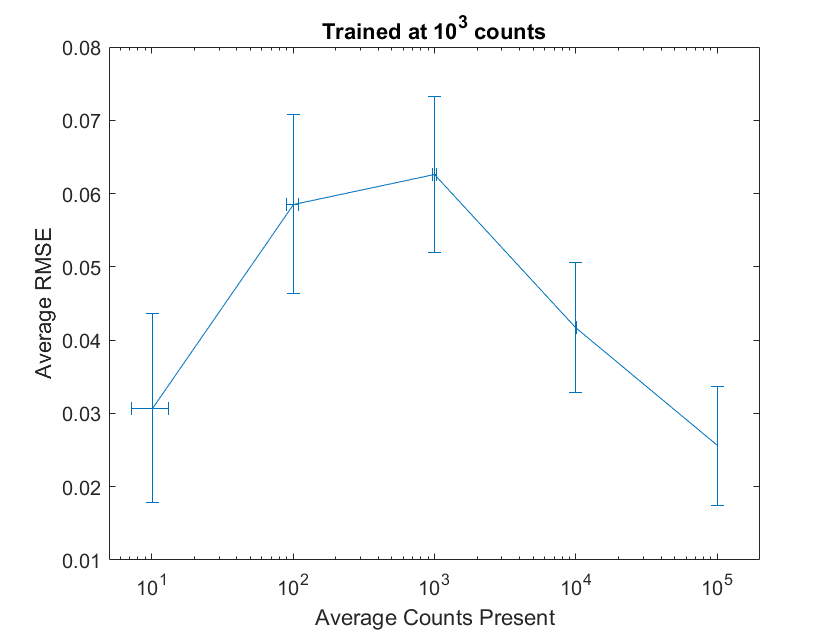

x = 2

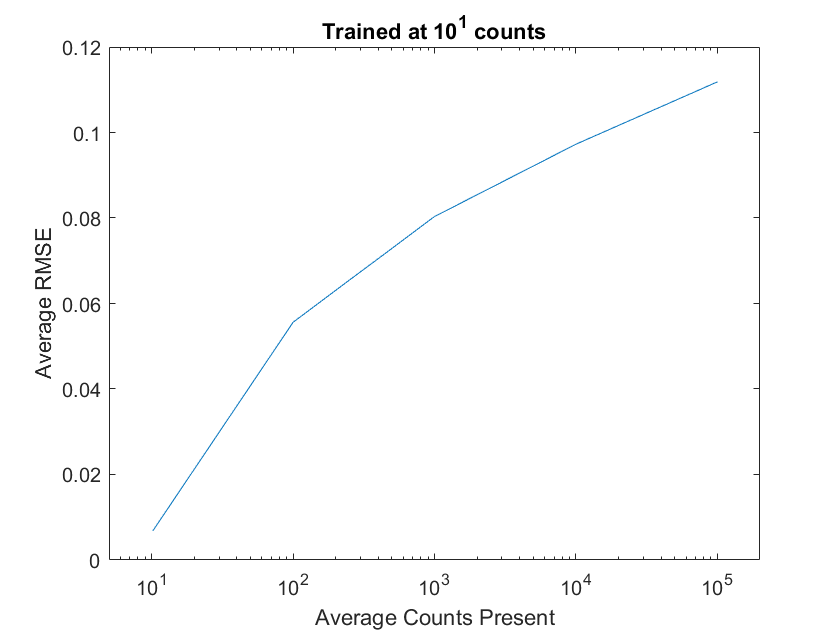

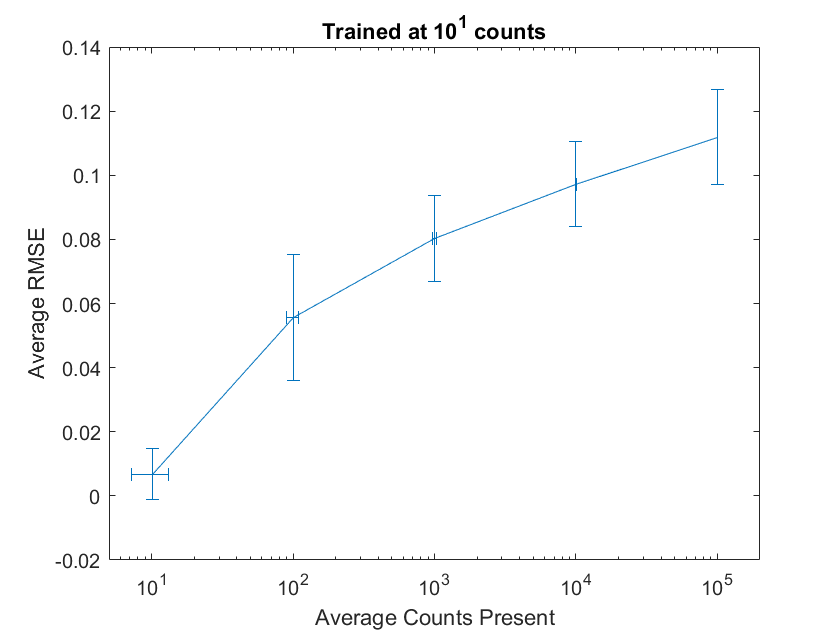

x = 3

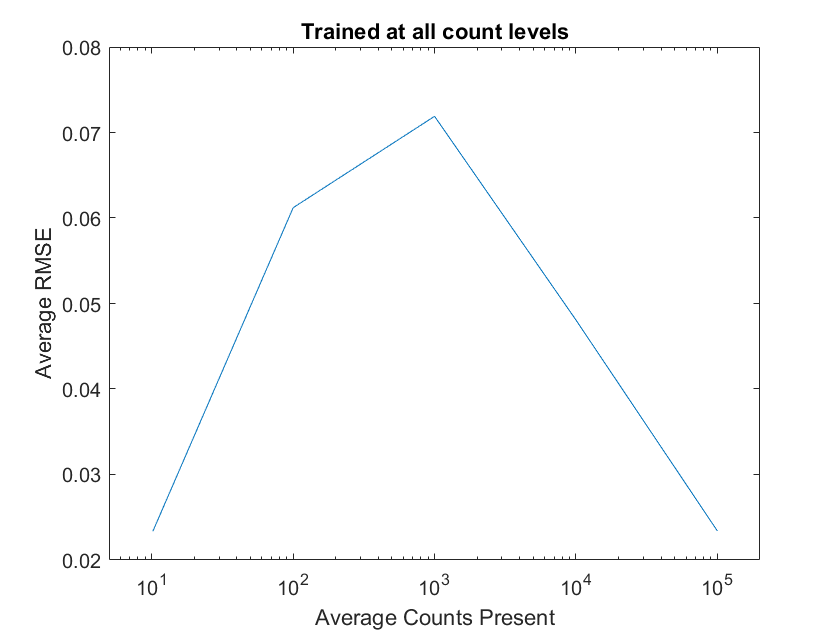

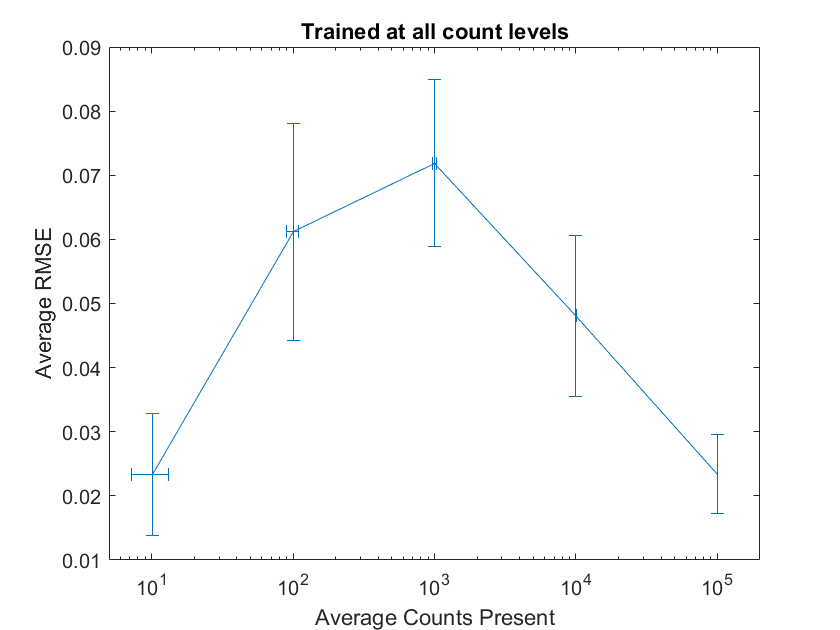

x = 4

% This script was used to assess the results of processing images with
% different signal levels (number of individual particle events present) 
% through a network trained for a different specific signal level.

% MPhys Research Project 2022/23
% Ross Anderson (H00295702)



clc
clear
close all

% set the run number, this is indicated by the gdrive file
run_choices = [21, 22, 23, 26];

for x = 1:length(run_choices)

    run_no = run_choices(x);

    % count_level = ["5.10^0", "10^1", "5.10^1", "10^2", "5.10^2", "10^3", "5.10^3", "10^4", "5.10^4", "10^5", "5.10^5", "10^6", "5.10^6", "10^7", "5.10^7", "10^8"];
    % count_level_notstring = [5e0, 1e1, 5e1, 1e2, 5e2, 1e3, 5e3, 1e4, 5e4, 1e5, 5e5, 1e6, 5e6, 1e7, 5e7, 1e8];

    count_level = ["10^1", "10^2", "10^3", "10^4", "10^5"];
    count_level_notstring = [1e1, 1e2, 1e3, 1e4, 1e5];

    avg_rmse = zeros(1, length(count_level));
    std_rmse = zeros(1, length(count_level));

    avg_rmse2 = zeros(1, length(count_level));
    std_rmse2 = zeros(1, length(count_level));

    avg_mse = zeros(1, length(count_level));
    std_mse = zeros(1, length(count_level));

    avg_counts = zeros(1, length(count_level));
    std_counts = zeros(1, length(count_level));

    for i = 1:length(count_level)

        % load all aspects of that run
        load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\"+count_level(i)+"\\results_process.mat");
        % load("G:\My Drive\MPhys Project\run_"+run_no+"\history.mat");
        images_sampled_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\"+count_level(i)+"\\centroid_process.mat");
        images_gaussfilt_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\"+count_level(i)+"\\gaussfilt_process.mat");
        % images_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\images.mat");
        coeffs = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\"+count_level(i)+"\\coeffs_process.mat");
        % coeffs = coeffs.coeffs;

        images_sampled_mat = images_sampled_mat.images_sampled_mat;
        images_gaussfilt_mat = images_gaussfilt_mat.images_gaussfilt_mat;

        % convert the network_output in the correct dimensionality
        network_output = results.predictions;
        network_output = permute(network_output, [2, 3, 1]);

        gaussfilt_summed = zeros(96, 96);
        sampled_summed = zeros(96, 96);
        output_summed = zeros(96, 96);

        rmse = zeros(1, 500);
        rmse2 = zeros(1, 500);
        mse = zeros(1, 500);

        for N = 1:500

            gaussfilt_tot = flipcat_4fold(images_gaussfilt_mat(:,:,N));
            %     showim(gaussfilt_tot, 1)
            %     title("Network input")
            %     shading flat

            sampled_tot = flipcat_4fold(images_sampled_mat(:,:,N));
            %     showim(sampled_tot, 1)
            %     title("Truth")
            %     shading flat

            network_output_tot = flipcat_4fold(network_output(:, :, N));
            %     showim(network_output_tot, 1)
            %     title("Network output")
            %     shading flat

            gaussfilt_tot = rescale(gaussfilt_tot);
            sampled_tot = rescale(sampled_tot);
            network_output_tot = rescale(network_output_tot);

            [row, col] = find(gaussfilt_tot);

            for k = 1:length(row)
                gaussfilt2(k) = gaussfilt_tot(row(k), col(k));
                sampled2(k) = sampled_tot(row(k), col(k));
                network_output2(k) = network_output_tot(row(k), col(k));
            end

            rmse(N) = sqrt(mean((sampled_tot(:)-network_output_tot(:)).^2));
            rmse2(N) = sqrt(mean((network_output2(:)-sampled2(:)).^2));
            mse(N) = mean((sampled_tot(:)-network_output_tot(:)).^2);


            %             rmse_inputvsoutput(N) = sqrt(mean((gaussfilt_tot(:)-network_output_tot(:)).^2));

        end

        rmse2 = rmse2(~isnan(rmse2));

        avg_rmse(i) = mean(rmse);
        std_rmse(i) = std(rmse);

        avg_rmse2(i) = mean(rmse2);
        std_rmse2(i) = std(rmse2);

        avg_mse(i) = mean(mse);
        std_mse(i) = std(mse);

        %         avg_rmse_inputvsoutput(i) = mean(rmse_inputvsoutput);
        %         std_rmse_inputvsoutput(i) = std(rmse_inputvsoutput);


        counts_present = coeffs.coeffs.counts;
        std_counts(i) = std(counts_present);
        avg_counts(i) = mean(counts_present);

        %         all_rmse{i} = rmse;
        %         all_rmse2{i} = rmse2;
        %         all_mse{i} = mse;
        %         all_rmse_inputvsoutput{ix} = rmse_inputvsoutput;

    end

    %     all_rmse_total{x} = all_rmse;
    %     all_rmse2_total{x} = all_rmse2;
    %     all_mse_total{x} = all_mse;
    %     all_rmse_inputvsoutput_total{x} = all_rmse_inputvsoutput;


    figure()
    semilogx(avg_counts, avg_rmse)
    if run_no == 21
        title("Trained at " + count_level(5) + " counts")
        counts{1} = avg_counts;
        rmse_total{1} = avg_rmse;
        rmse2_total{1} = avg_rmse2;
    elseif run_no == 22
        title("Trained at " + count_level(3) + " counts")
        counts{2} = avg_counts;
        rmse_total{2} = avg_rmse;
        rmse2_total{2} = avg_rmse2;
    elseif run_no == 23
        title("Trained at " + count_level(1) + " counts")
        counts{3} = avg_counts;
        rmse_total{3} = avg_rmse;
        rmse2_total{3} = avg_rmse2;
    elseif run_no == 26
        title("Trained at all count levels")
        counts{4} = avg_counts;
        rmse_total{4} = avg_rmse;
        rmse2_total{4} = avg_rmse2;

    end
    xlabel("Average Counts Present")
    ylabel("Average RMSE")
    xlim([5*10^0, 2*10^5])

    %     lowlim = count_level_notstring(3)/15;
    %     highlim = count_level_notstring(3)*15;
    %     xlim([lowlim, highlim])

    %     figure()
    %     semilogx(count_level_notstring, avg_mse)
    %     title("Trained at " + count_level(3) + " counts")
    %     xlabel("Counts Present")
    %     ylabel("Average MSE")

    figure()
    errorbar(avg_counts, avg_rmse, std_rmse, std_rmse, std_counts, std_counts)
    set(gca,'XScale','log');
    if run_no == 21
        title("Trained at " + count_level(5) + " counts")
        uncertainty_counts{1} = std_counts;
        uncertainty_rmse{1} = std_rmse;
        uncertainty_rmse2{1} = std_rmse2;
    elseif run_no == 22
        title("Trained at " + count_level(3) + " counts")
        uncertainty_counts{2} = std_counts;
        uncertainty_rmse{2} = std_rmse;
        uncertainty_rmse2{2} = std_rmse2;
    elseif run_no == 23
        title("Trained at " + count_level(1) + " counts")
        uncertainty_counts{3} = std_counts;
        uncertainty_rmse{3} = std_rmse;
        uncertainty_rmse2{3} = std_rmse2;
    elseif run_no == 26
        title("Trained at all count levels")
        uncertainty_counts{4} = std_counts;
        uncertainty_rmse{4} = std_rmse;
        uncertainty_rmse2{4} = std_rmse2;

    end
    xlabel("Average Counts Present")
    ylabel("Average RMSE")
    xlim([5*10^0, 2*10^5])

    %     lowlim = count_level_notstring(3)/15;
    %     highlim = count_level_notstring(3)*15;
    %     xlim([lowlim, highlim])

    x
end

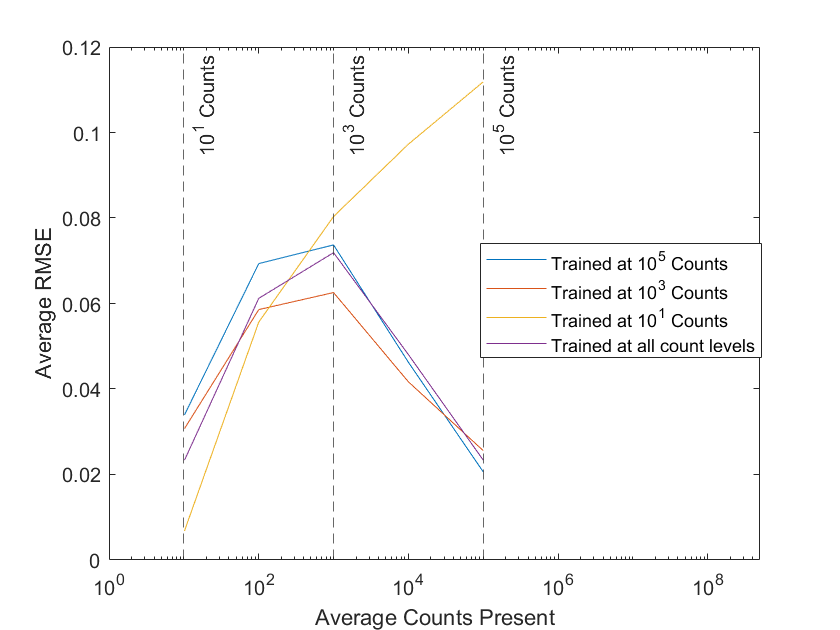


figure()
semilogx(counts{1}, rmse_total{1})
hold on
semilogx(counts{2}, rmse_total{2})
semilogx(counts{3}, rmse_total{3})
semilogx(counts{4}, rmse_total{4})
xline([10^1, 10^3, 10^5], '--', ["10^1 Counts", "10^3 Counts", "10^5 Counts"])
hold off
legend("Trained at 10^5 Counts", "Trained at 10^3 Counts", "Trained at 10^1 Counts", "Trained at all count levels", 'Position',[0.5875 0.450000000000001 0.302976190476191 0.145238095238095])
xlim([10^0, 5*10^8])
xlabel("Average Counts Present")
ylabel("Average RMSE")

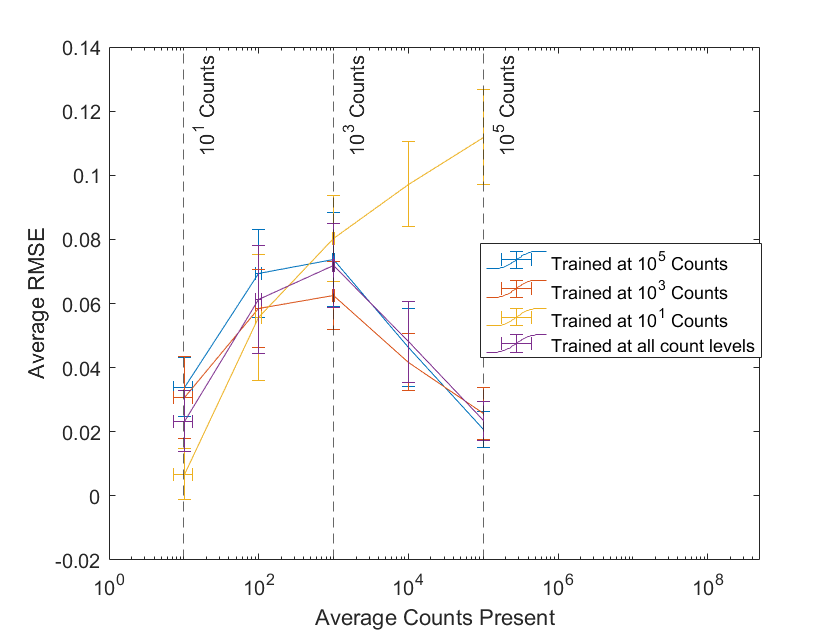



figure()
errorbar(counts{1}, rmse_total{1}, uncertainty_rmse{1}, uncertainty_rmse{1}, uncertainty_counts{1}, uncertainty_counts{1})
hold on
errorbar(counts{2}, rmse_total{2}, uncertainty_rmse{2}, uncertainty_rmse{2}, uncertainty_counts{2}, uncertainty_counts{2})
errorbar(counts{3}, rmse_total{3}, uncertainty_rmse{3}, uncertainty_rmse{3}, uncertainty_counts{3}, uncertainty_counts{3})
errorbar(counts{4}, rmse_total{4}, uncertainty_rmse{4}, uncertainty_rmse{4}, uncertainty_counts{4}, uncertainty_counts{4})
xline([10^1, 10^3, 10^5], '--', ["10^1 Counts", "10^3 Counts", "10^5 Counts"])
hold off
set(gca,'XScale','log');
legend("Trained at 10^5 Counts", "Trained at 10^3 Counts", "Trained at 10^1 Counts", "Trained at all count levels", 'Position',[0.5875 0.450000000000001 0.302976190476191 0.145238095238095])
xlim([10^0, 5*10^8])
xlabel("Average Counts Present")
ylabel("Average RMSE")

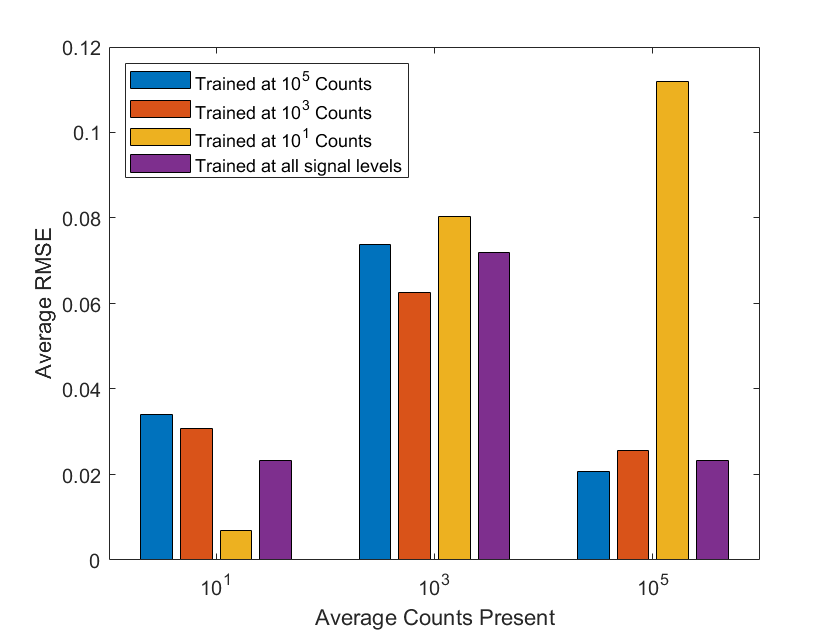



y = [rmse_total{1}(1) rmse_total{2}(1) rmse_total{3}(1) rmse_total{4}(1); rmse_total{1}(3) rmse_total{2}(3) rmse_total{3}(3) rmse_total{4}(3); rmse_total{1}(5) rmse_total{2}(5) rmse_total{3}(5) rmse_total{4}(5);];

figure()
bar(y)
legend("Trained at 10^5 Counts", "Trained at 10^3 Counts", "Trained at 10^1 Counts", "Trained at all signal levels", 'location', 'northwest')
xlabel("Average Counts Present")
ylabel("Average RMSE")
set(gca,'XTickLabel',{'10^1','10^3','10^5'});

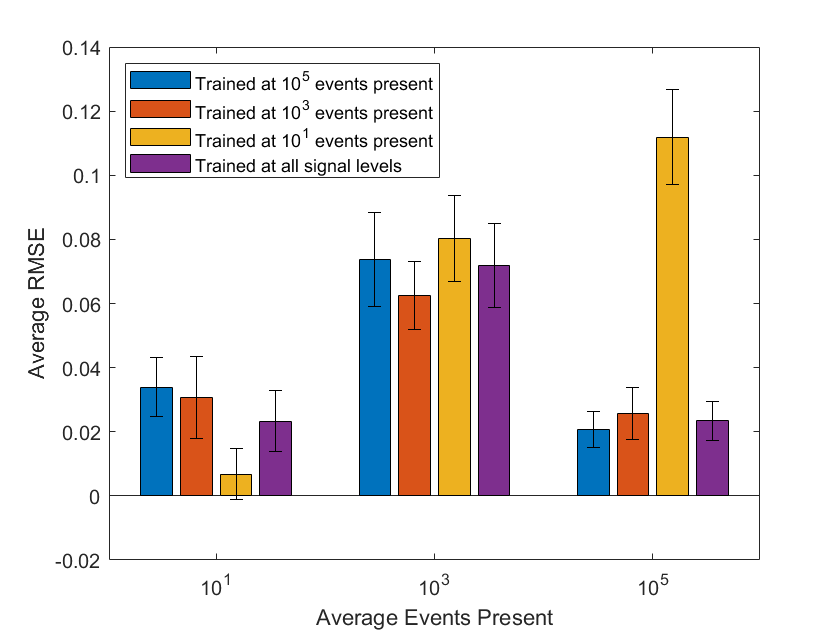



figure()
y = [rmse_total{1}(1) rmse_total{2}(1) rmse_total{3}(1) rmse_total{4}(1); rmse_total{1}(3) rmse_total{2}(3) rmse_total{3}(3) rmse_total{4}(3); rmse_total{1}(5) rmse_total{2}(5) rmse_total{3}(5) rmse_total{4}(5)];
y2 = [rmse2_total{1}(1) rmse2_total{2}(1) rmse2_total{3}(1) rmse2_total{4}(1); rmse2_total{1}(3) rmse2_total{2}(3) rmse2_total{3}(3) rmse2_total{4}(3); rmse2_total{1}(5) rmse2_total{2}(5) rmse2_total{3}(5) rmse2_total{4}(5)];

errhigh = [uncertainty_rmse{1}(1) uncertainty_rmse{2}(1) uncertainty_rmse{3}(1) uncertainty_rmse{4}(1); uncertainty_rmse{1}(3) uncertainty_rmse{2}(3) uncertainty_rmse{3}(3) uncertainty_rmse{4}(3); uncertainty_rmse{1}(5) uncertainty_rmse{2}(5) uncertainty_rmse{3}(5) uncertainty_rmse{4}(5)];
errlow = errhigh;

errhigh2 = [uncertainty_rmse2{1}(1) uncertainty_rmse2{2}(1) uncertainty_rmse2{3}(1) uncertainty_rmse2{4}(1); uncertainty_rmse2{1}(3) uncertainty_rmse2{2}(3) uncertainty_rmse2{3}(3) uncertainty_rmse2{4}(3); uncertainty_rmse2{1}(5) uncertainty_rmse2{2}(5) uncertainty_rmse2{3}(5) uncertainty_rmse2{4}(5)];
errlow2 = errhigh2;

b = bar(y);
hold on
[ngroups,nbars] = size(y);
% Get the x coordinate of the bars
x = nan(nbars, ngroups);
for i = 1:nbars
    x(i,:) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(x',y,errhigh,'k','linestyle','none');
hold off
legend("Trained at 10^5 events present", "Trained at 10^3 events present", "Trained at 10^1 events present", "Trained at all signal levels", 'location', 'northwest')
xlabel("Average Events Present")
ylabel("Average RMSE")
set(gca,'XTickLabel',{'10^1','10^3','10^5'});

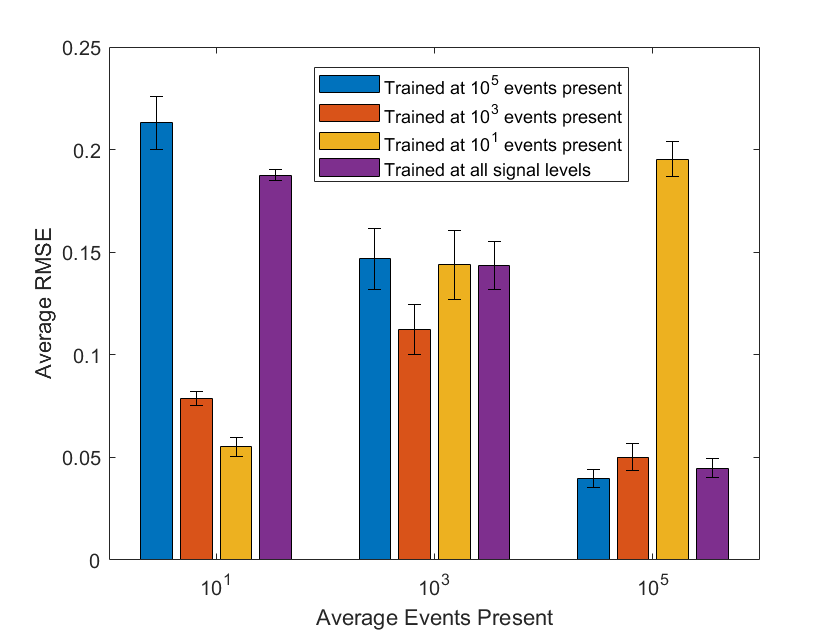



figure()
b2 = bar(y2);
hold on
[ngroups,nbars] = size(y);
% Get the x coordinate of the bars
x2 = nan(nbars, ngroups);
for i = 1:nbars
    x2(i,:) = b2(i).XEndPoints;
end
% Plot the errorbars
errorbar(x2',y2,errhigh2,'k','linestyle','none');
hold off
legend("Trained at 10^5 events present", "Trained at 10^3 events present", "Trained at 10^1 events present", "Trained at all signal levels", 'Position', [0.373809521556177 0.710714285714287 0.375595238095238 0.182936507936508]);
xlabel("Average Events Present")
ylabel("Average RMSE")
set(gca,'XTickLabel',{'10^1','10^3','10^5'});